Graph generation

clear  all
% Values from paper
L11_q = 0.762841;
L12_q = 0.689760;
L2_q = 0.555778;
L3_q = 0.296565;

filenames = ["data\base\level_11_q.txt" "data\base\level_12_q.txt" "data\base\level_2_q.txt" "data\base\level_3_q.txt"];
linenames = ["Level 11" "Level 12" "Level 2" "Level 3"]

linenames = 1×4 string array
    "Level 11"    "Level 12"    "Level 2"    "Level 3"



data = [];
importfiltered = [];
importq = [];
importvar = [];
for i = 1 : length(filenames)
    data = [data importdata(filenames(i))];
    length(data)
    importfiltered = [importfiltered data(3:length(data),i)];
    importq = [importq data(1,i)];
    importvar = [importvar data(2,i)];
end

ans = 102

ans = 102

ans = 102

ans = 102

importfiltered =     0.4861    0.4584    0.4276    0.3860
    0.5109    0.6518    0.4690    0.2718
    0.5064    0.5756    0.6476    0.4870
    0.4533    0.6563    0.5825    0.3787
    0.5887    0.5785    0.4427    0.3949
    0.6514    0.6741    0.5886    0.4848
    0.5660    0.4535    0.5716    0.3423
    0.4998    0.5457    0.5355    0.3603
    0.5543    0.6315    0.5004    0.4280
    0.5250    0.5920    0.5341    0.4818


importq =     0.5361    0.5262    0.4976    0.3892


importvar =     0.0066    0.0085    0.0077    0.0051


ans =     0.4861
    0.5109
    0.5064
    0.4533
    0.5887
    0.6514
    0.5660
    0.4998
    0.5543
    0.5250


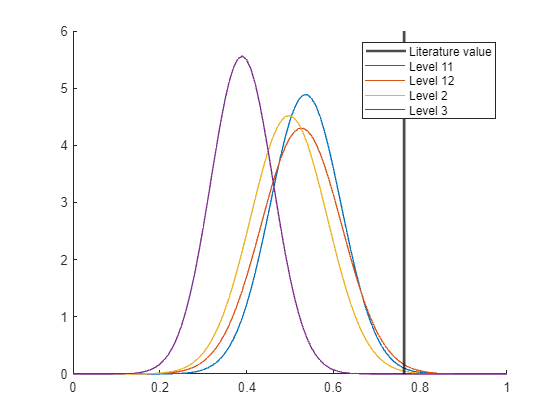


normalpd = [];
xvalues = 0:0.01:1;
PDFs = [];
x1 = xline(L11_q, 'DisplayName', 'Literature value');
x1.LineWidth = 2;
x1.Color = "black";
hold on;
for i = 1 : width(importfiltered)
    normalpd = fitdist(importfiltered(1:length(importfiltered),i), "Normal");
    PDF = pdf(normalpd, xvalues);
    plot(xvalues, PDF, 'DisplayName', linenames(i));
end

legend